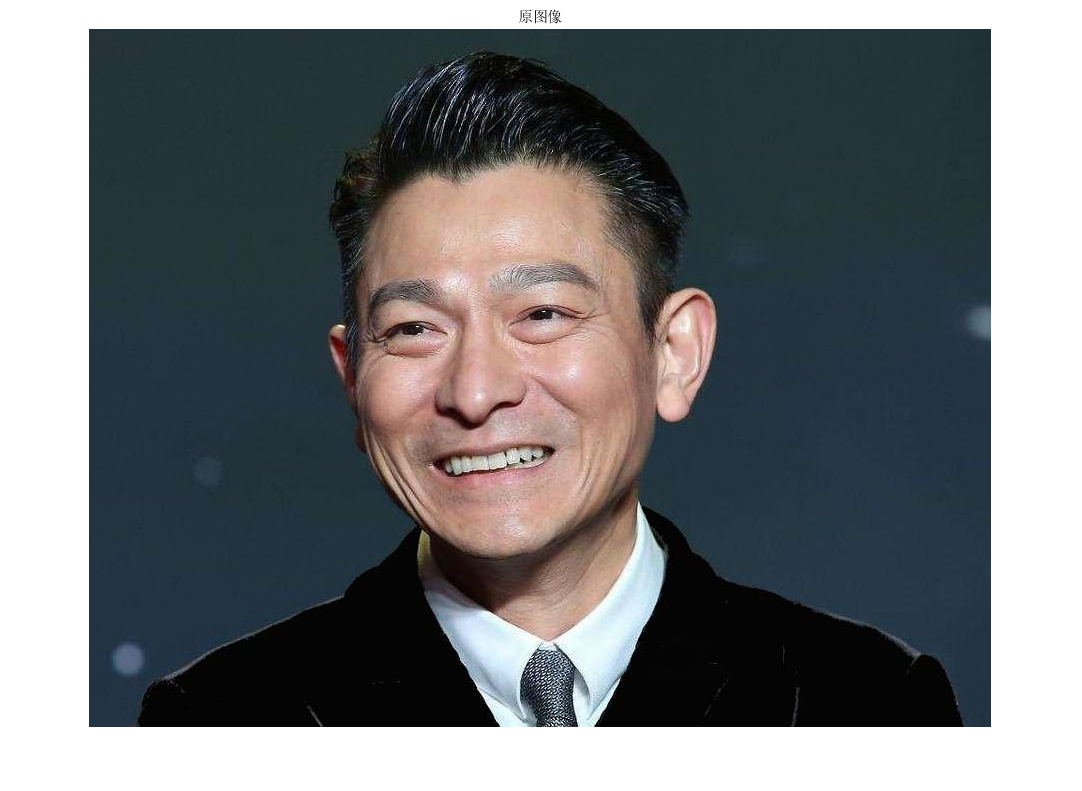

clc;
clear;
I=imread("05-刘德华.tif");
figure(1)
imshow(I);
title("原图像");

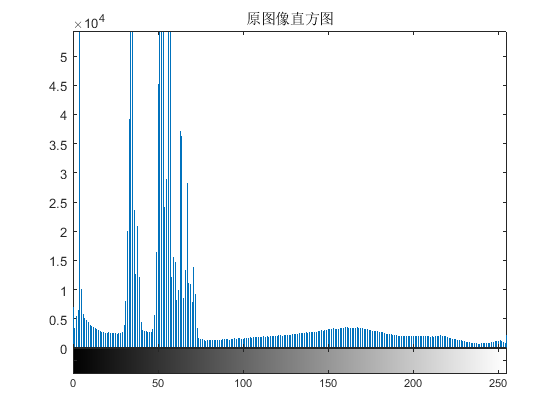

figure
imhist(I)
title("原图像直方图")

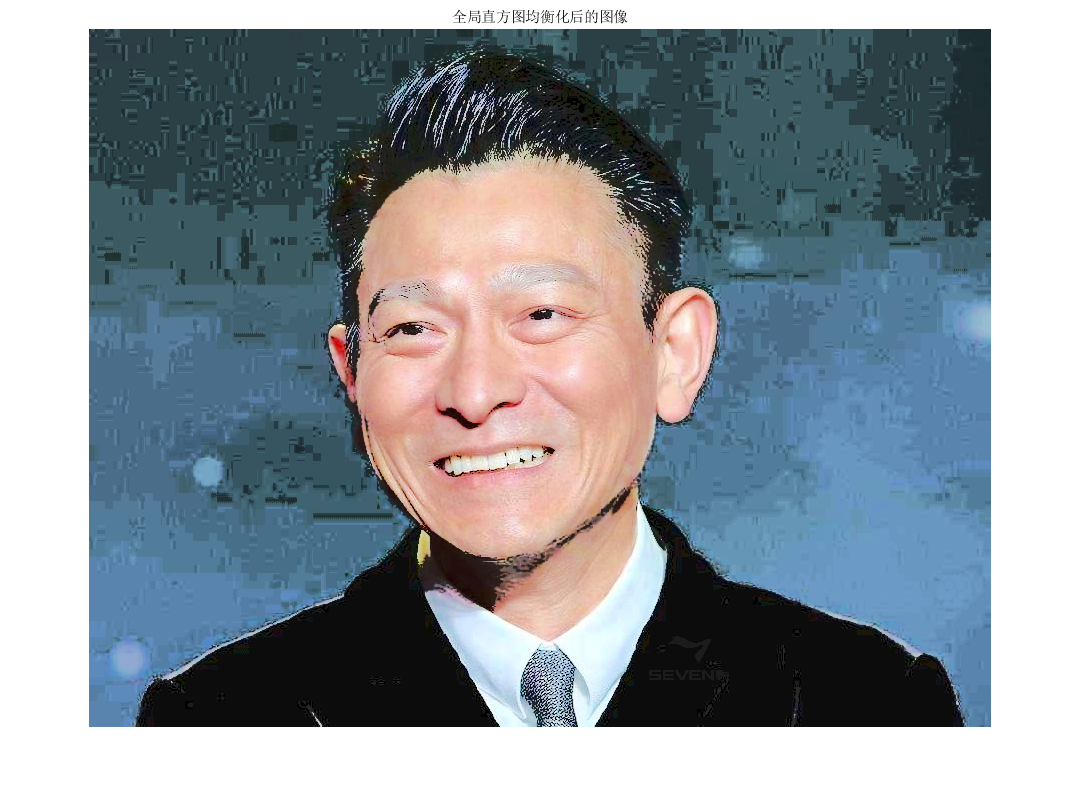

%全局直方图均衡化
%将rgb通道转换成hsv通道
I_hsv=rgb2hsv(I);
%对v通道（亮度）进行直方图均衡化
I_hsv(:,:,3)=histeq(I_hsv(:,:,3));
%转变回RGB图像
I_eq=im2uint8(hsv2rgb(I_hsv));
figure()
imshow(I_eq);
title("全局直方图均衡化后的图像")

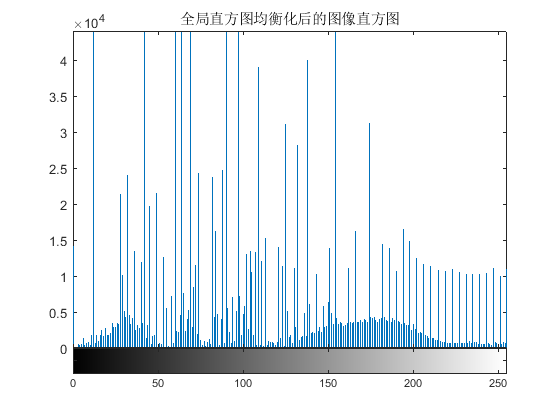

figure
imhist(I_eq)
title("全局直方图均衡化后的图像直方图")

disp("全局直方图均衡化增强后，衣服logo不够清晰，不够明显");

全局直方图均衡化增强后，衣服logo不够清晰，不够明显


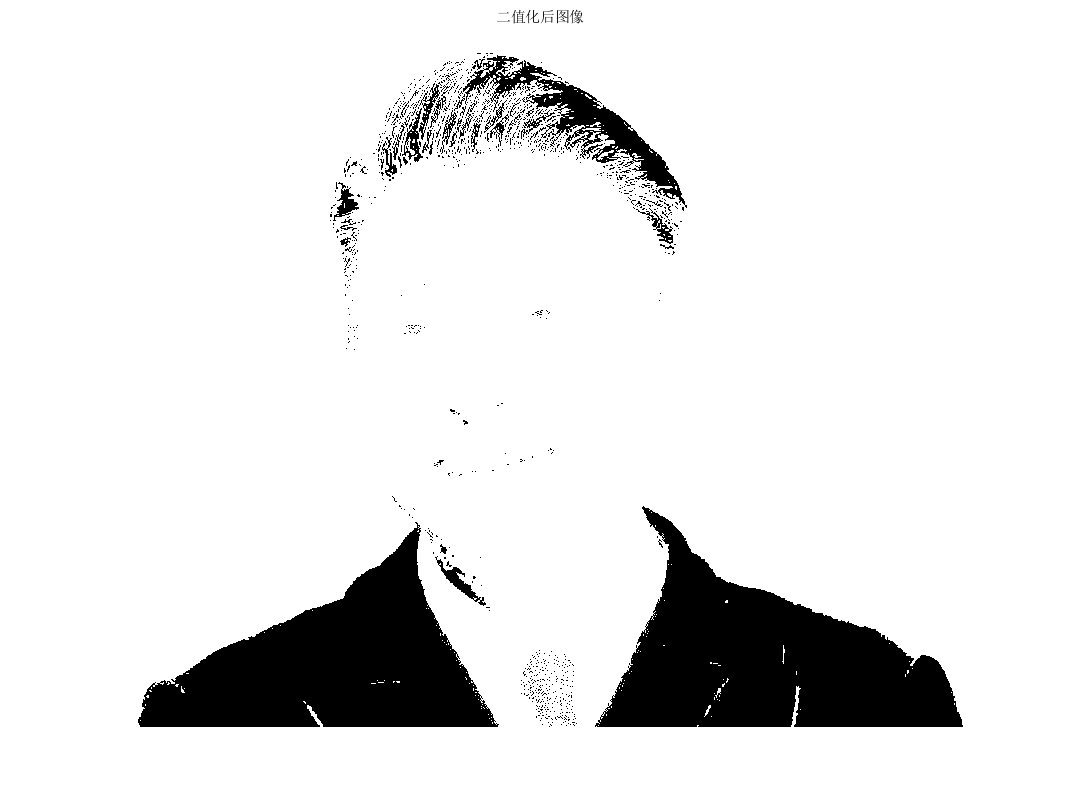

%局部直方图均衡化
%首先提取衣服区域
%将原图像二值化
I_bin=imbinarize(rgb2gray(I),0.05);
figure
imshow(I_bin);
title("二值化后图像");

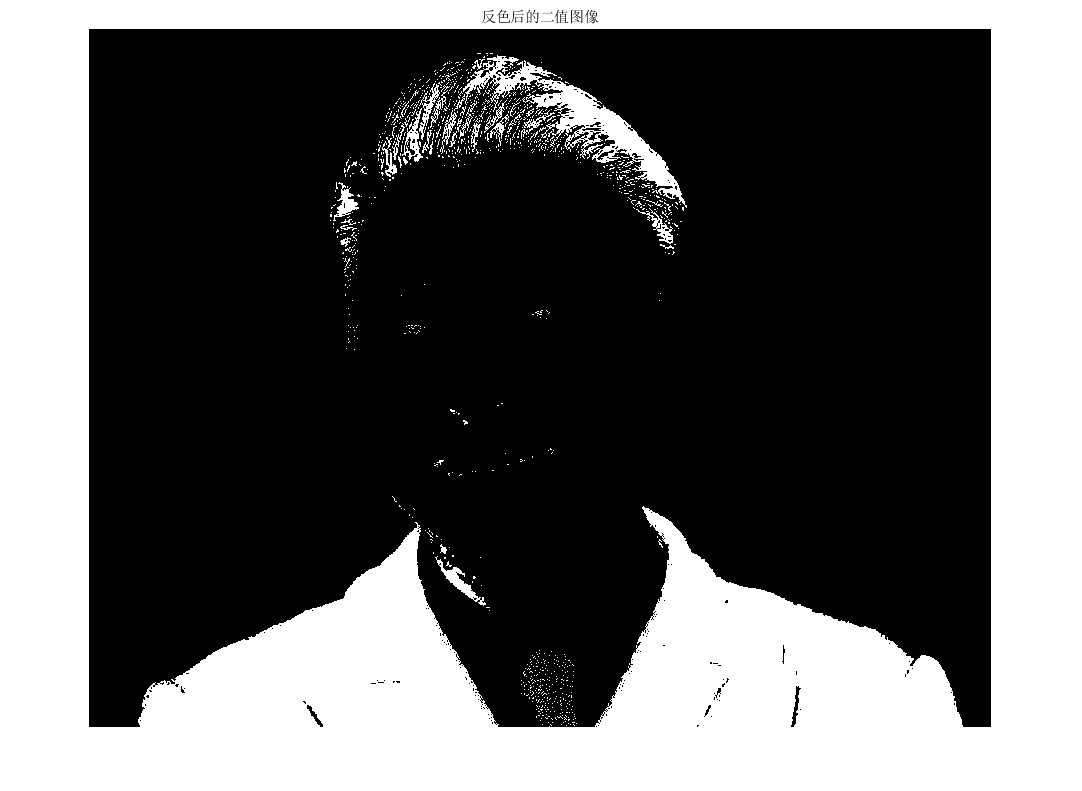

%将图像反色
I_bin=1-I_bin;
figure
imshow(I_bin);
title("反色后的二值图像");

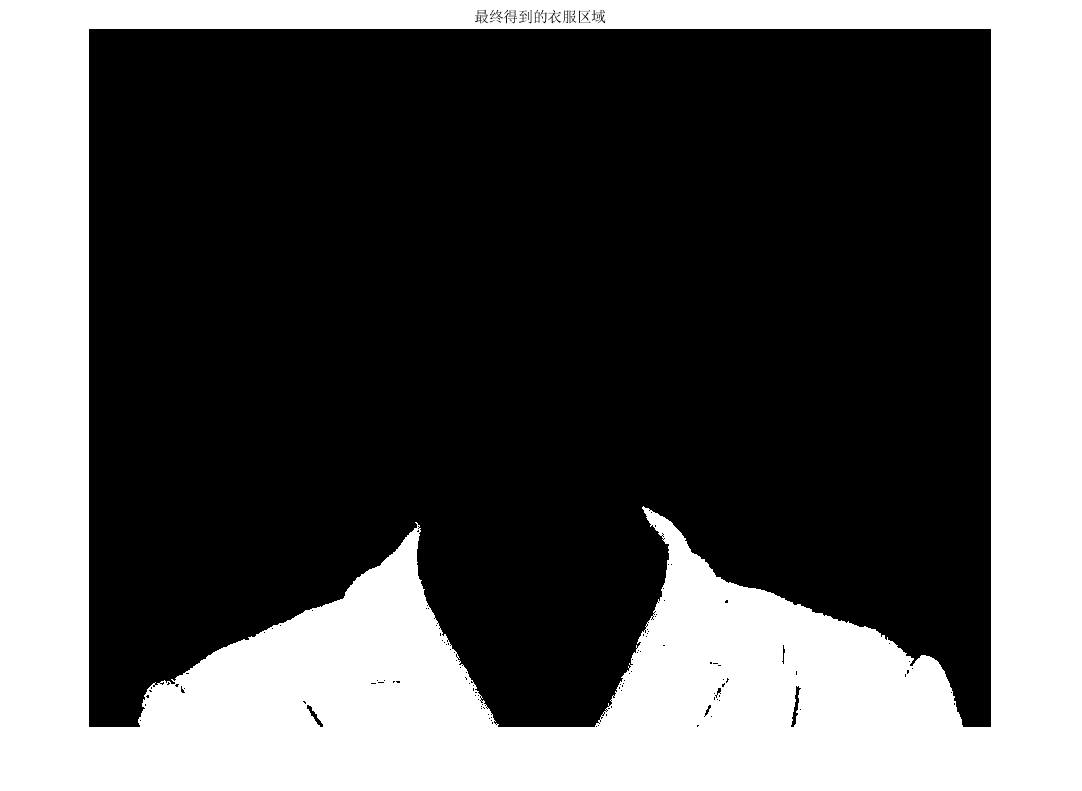

%去除小区域
I_bin=bwareaopen(I_bin,10000);  
figure
imshow(I_bin)
title("最终得到的衣服区域");

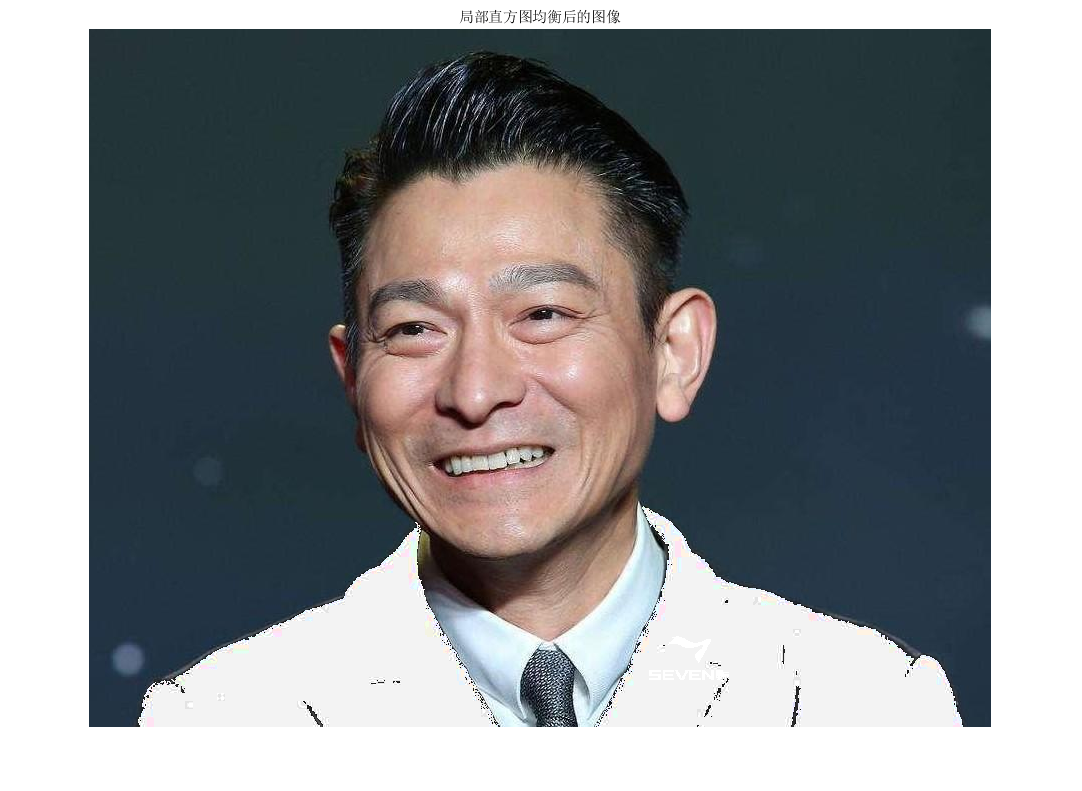

%对衣服区域进行直方图均衡增强
temp=uint8(repmat(I_bin,[1,1,3]));
I_temp=histeq(I.*temp);
I_parteq=I_temp.*temp+I.*uint8(repmat(1-I_bin,[1,1,3]));
figure
imshow(I_parteq);
title("局部直方图均衡后的图像");

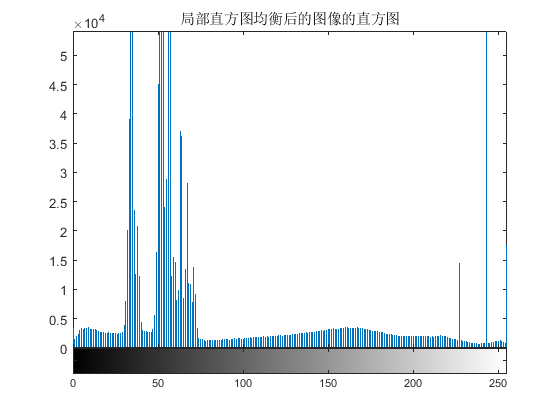

figure
imhist(I_parteq);
title("局部直方图均衡后的图像的直方图");

disp("局部直方图均衡化增强后，衣服logo可见");

局部直方图均衡化增强后，衣服logo可见


%储存
imwrite(I_eq,'全局直方图均衡化增强后的图片.jpg','jpg');
imwrite(I_parteq,'局部直方图均衡化增强后的图片.jpg','jpg');